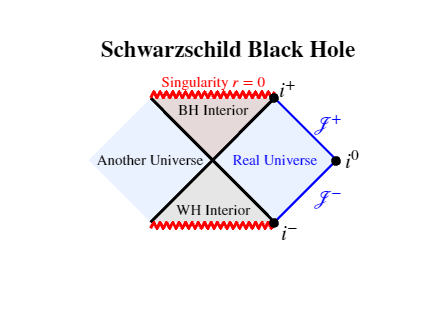


% PENROSE_DIAGRAMS_FINAL_MARKED_ON_PLOT
% Draws Schwarzschild and Reissner-Nordstrom diagrams.
% Explicitly labels conformal infinity points (i0, i+, i-, Scri) ON THE PLOT directly.

    % Clear environment
    close all; clc;

    % Global formatting settings
    set(0, 'DefaultTextInterpreter', 'latex');
    set(0, 'DefaultAxesFontSize', 14);

    %% 1. Schwarzschild Black Hole (Marked on Plot)
    figure('Name', 'Schwarzschild Marked', 'Color', 'w', 'Position', [100, 100, 800, 600]);
    hold on; axis equal; axis off;
    xlim([-2.5, 3.0]); ylim([-1.5, 1.5]); % Extended xlim for labels

    % Define Colors
    col_I   = [0.92, 0.95, 1.0]; 
    col_II  = [0.9, 0.85, 0.85]; 
    col_III = [0.9, 0.9, 0.9];   
    col_IV  = [0.92, 0.95, 1.0]; 

    % Draw Regions
    fill([0, 1, 2, 1], [0, 1, 0, -1], col_I, 'EdgeColor', 'none');
    fill([0, -1, -2, -1], [0, 1, 0, -1], col_IV, 'EdgeColor', 'none');
    fill([0, 1, -1], [0, 1, 1], col_II, 'EdgeColor', 'none');
    fill([0, 1, -1], [0, -1, -1], col_III, 'EdgeColor', 'none');

    % Boundaries & Singularities
    LW = 2;
    plot([-1, 1], [-1, 1], 'k-', 'LineWidth', LW); % H+
    plot([-1, 1], [1, -1], 'k-', 'LineWidth', LW); % H-
    
    % Null Infinity Lines (Explicitly drawn for labeling)
    plot([1, 2], [1, 0], 'b-', 'LineWidth', 1.5); % Scri+ Region I
    plot([1, 2], [-1, 0], 'b-', 'LineWidth', 1.5); % Scri- Region I

    % Singularities
    draw_zigzag([-1, 1], 1.05, 'r');  
    draw_zigzag([-1, 1], -1.05, 'r'); 

    % --- POINTS & LABELS ON DIAGRAM ---
    % Region Labels
    text(0.3, 0, 'Real Universe', 'FontSize', 10, 'FontWeight', 'bold', 'Color', 'b');
    text(-1.9, 0, 'Another Universe', 'FontSize', 10, 'FontWeight', 'bold');
    text(0, 0.8, 'BH Interior', 'FontSize', 10, 'HorizontalAlignment', 'center');
    text(0, -0.8, 'WH Interior', 'FontSize', 10, 'HorizontalAlignment', 'center');

    % Mark Special Points with Dots
    plot(2, 0, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 6); % i0
    plot(1, 1, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 6); % i+
    plot(1, -1, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 6); % i-

    % Text Labels for Special Points (Directly on diagram)
    text(2.1, 0, '$i^0$', 'FontSize', 14, 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle'); 
    text(1.2, 1.15, '$i^+$', 'FontSize', 14, 'HorizontalAlignment', 'center'); 
    text(1.23, -1.15, '$i^-$', 'FontSize', 14, 'HorizontalAlignment', 'center'); 
    
    % Text Labels for Null Infinity (Scri)
    text(1.6, 0.6, '$\mathcal{J}^+$', 'FontSize', 14, 'Color', 'b', 'HorizontalAlignment', 'left'); 
    text(1.6, -0.6, '$\mathcal{J}^-$', 'FontSize', 14, 'Color', 'b', 'HorizontalAlignment', 'left'); 

    text(0, 1.25, 'Singularity $r=0$', 'Color', 'r', 'HorizontalAlignment', 'center');
    title('\textbf{Schwarzschild Black Hole} ');

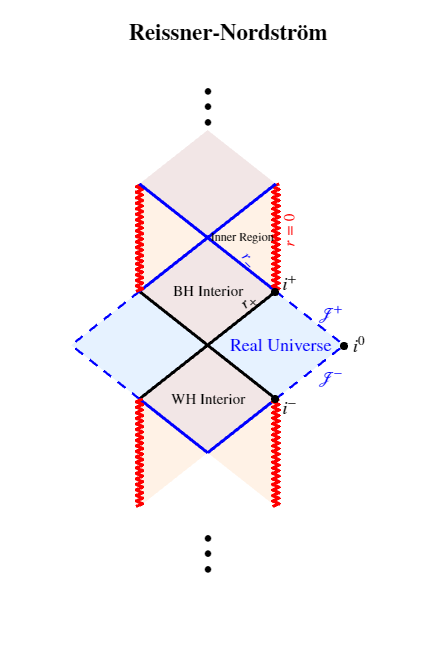

    %% 2. Reissner-Nordstrom Black Hole (Marked on Plot)
    figure('Name', 'RN Marked', 'Color', 'w', 'Position', [950, 50, 600, 900]);
    hold on; axis off;
    axis([-2.2 2.8 -4.5 5.5]); % Extended xlim for labels

    % Colors
    c_out = [0.9, 0.95, 1];   
    c_bh  = [0.95, 0.9, 0.9]; 
    c_in  = [1, 0.95, 0.9];   

    % === CENTRAL BLOCK ===
    fill([0, 1, 0, -1], [0, 1, 2, 1], c_bh, 'EdgeColor', 'none'); % Region II
    fill([0, 1, 2, 1], [0, 1, 0, -1], c_out, 'EdgeColor', 'none'); % Region I
    fill([0, -1, -2, -1], [0, 1, 0, -1], c_out, 'EdgeColor', 'none'); % Region I'
    fill([0, 1, 0, -1], [0, -1, -2, -1], c_bh, 'EdgeColor', 'none'); % Region II'

    % Draw Lines
    plot([0, 1], [0, 1], 'k-', 'LineWidth', 2); % r+
    plot([0, -1], [0, 1], 'k-', 'LineWidth', 2); 
    plot([0, 1], [0, -1], 'k-', 'LineWidth', 2); 
    plot([0, -1], [0, -1], 'k-', 'LineWidth', 2);
    
    % Null Infinities for Central Block
    plot([1, 2], [1, 0], 'b--', 'LineWidth', 1.5); % Scri+
    plot([1, 2], [-1, 0], 'b--', 'LineWidth', 1.5); % Scri-
    plot([-1, -2], [1, 0], 'b--', 'LineWidth', 1.5);
    plot([-1, -2], [-1, 0], 'b--', 'LineWidth', 1.5);

    % === FUTURE EXTENSION ===
    fill([-1, 0, -1], [1, 2, 3], c_in, 'EdgeColor', 'none'); 
    fill([1, 0, 1], [1, 2, 3], c_in, 'EdgeColor', 'none');   
    plot([0, 1], [2, 1], 'b-', 'LineWidth', 2); % r-
    plot([0, -1], [2, 1], 'b-', 'LineWidth', 2);
    draw_zigzag_vertical(-1, 1, 3, 'r'); 
    draw_zigzag_vertical(1, 1, 3, 'r');

    % Next Universe (Top Diamond) - Filled with II color as requested previously
    fill([0, 1, 0, -1], [2, 3, 4, 3], c_bh, 'EdgeColor', 'none'); 
    plot([0, 1], [2, 3], 'b-', 'LineWidth', 2); 
    plot([0, -1], [2, 3], 'b-', 'LineWidth', 2);
    
    % Explicit Lines for Top Diamond Scri (to label if needed, or leave implied)
    %plot([1, 2], [3, 2], 'b-', 'LineWidth', 1.5); 
    %plot([-1, -2], [3, 2], 'b-', 'LineWidth', 1.5); 

    % === PAST EXTENSION ===
    fill([-1, 0, -1], [-1, -2, -3], c_in, 'EdgeColor', 'none');
    fill([1, 0, 1], [-1, -2, -3], c_in, 'EdgeColor', 'none');
    plot([0, 1], [-2, -1], 'b-', 'LineWidth', 2); 
    plot([0, -1], [-2, -1], 'b-', 'LineWidth', 2);
    draw_zigzag_vertical(-1, -3, -1, 'r'); 
    draw_zigzag_vertical(1, -3, -1, 'r');

    % === MARK POINTS & LABELS ON DIAGRAM (RN) ===
    % Region Labels
    text(0.3, 0, 'Real Universe', 'FontSize', 12, 'FontWeight', 'bold', 'Color', 'b');
    text(0, 1, 'BH Interior', 'HorizontalAlignment', 'center');
    text(0, -1, 'WH Interior', 'HorizontalAlignment', 'center');
    %text(0, 3, 'BH Interior', 'HorizontalAlignment', 'center');
    text(0.5,2,'Inner Region','FontSize', 7, 'HorizontalAlignment', 'center')
    
    % Points for Central Region I
    plot(2, 0, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 5); % i0
    plot(1, 1, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 5); % i+
    plot(1, -1, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 5); % i-

    % Text Labels for Central Region I
    text(2.1, 0, '$i^0$', 'FontSize', 12, 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle');
    text(1.2, 1.15, '$i^+$', 'FontSize', 12, 'HorizontalAlignment', 'center'); % Close to node
    text(1.2, -1.15, '$i^-$', 'FontSize', 12, 'HorizontalAlignment', 'center');
    
    text(1.6, 0.6, '$\mathcal{J}^+$', 'FontSize', 12, 'Color', 'b', 'HorizontalAlignment', 'left'); 
    text(1.6, -0.6, '$\mathcal{J}^-$', 'FontSize', 12, 'Color', 'b', 'HorizontalAlignment', 'left');

    % Infinite Dots
    text(0, 4.5, '$\vdots$', 'FontSize', 35, 'HorizontalAlignment', 'center');
    text(0, -3.8, '$\vdots$', 'FontSize', 35, 'HorizontalAlignment', 'center');
    
    % Horizon Labels
    text(0.5, 0.7, '$r_+$', 'Rotation', 45);
    text(0.5, 1.7, '$r_-$', 'Rotation', -45, 'Color', 'b');
    text(1.2, 1.8, '$r=0$', 'Rotation', 90, 'Color', 'r');

    title('\textbf{Reissner-Nordstr\"om}');



% --- LOCAL FUNCTIONS (Must be at end of file) ---


function draw_zigzag(xrange, y, color)
    x = linspace(xrange(1), xrange(2), 40);
    amp = 0.05;
    y_vals = y + amp * (-1).^(1:length(x));
    plot(x, y_vals, 'Color', color, 'LineWidth', 2);
end

function draw_zigzag_vertical(x, ystart, yend, color)
    y = linspace(ystart, yend, 40);
    amp = 0.05;
    x_vals = x + amp * (-1).^(1:length(y));
    plot(x_vals, y, 'Color', color, 'LineWidth', 2);
end